# Applied Mathematics

## Numerical Optimization

### Function derivatives

Jacobian, gradient and Hessian:

- Scalar-valued function: $\frac{\partial }{\partial x}f\left(x\right)$, $\nabla f\left(x\right)=\frac{\partial }{\partial x}{f\left(x\right)}^T$, $[\nabla f^2(x)]_{ij}=\frac{\partial f^2}{\partial x_i \partial x_j}(x)$

- Vector-valued function: ${\left\lbrack \frac{\partial }{\partial x}F\left(x\right)\right\rbrack }_{\textrm{ij}} =\frac{\partial }{\partial x_j }F_i \left(x\right)$, $\nabla F={\left(\frac{\partial }{\partial x}F\left(x\right)\right)}^T$, $[\nabla^2F(x)]_{ijk}=\frac{\partial F^2_i}{\partial x_j\partial x_k}(x)$

### Problem Definition

#### **general optimization problem**


$${\textrm{minimize}}_{x\in R^{n_v } } \;f\left(x\right)$$



$$\begin{array}{l}
\textrm{subject}\;\textrm{to}\;\textrm{Ax}\le b\\
A_{\textrm{eq}} x{=b}_{\textrm{eq}} \\
c\left(x\right)\le 0\\
c_{\textrm{eq}} \left(x\right)=0\\
l\le x\le u\;
\end{array}$$


- $l,u\in R^{n_v }$ are box constraints

- $c:R^{n_v } \to R^{n_{\textrm{ineq}}^{\textrm{nl}} }$ are nonlinear inequality constraints

- $c_{\textrm{eq}} :R^{n_v } \to R^{n_{\textrm{eq}}^{\textrm{nl}} }$ are nonlinear equality constraints

- $A\in R^{n_{\textrm{ineq}}^{\textrm{lin}} \times n_v }$ define linear inequality constraints

- $A_{\textrm{eq}} \in R^{n_{\textrm{eq}}^{\textrm{lin}} \times n_v }$ define linear equality constraints

#### **Lagrangian and Karush-Kuhn-Tucker (KKT) optimality conditions**


$${\textrm{minimize}}_{x\in R^{n_v } } \;f\left(x\right)$$



$$\begin{array}{l}
\textrm{subject}\;\textrm{to}\;g\left(x\right)\le 0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;h\left(x\right)=0
\end{array}$$


Lagrangian: $L(x,\lambda,\mu)=f(x)+\lambda^Tg(x)+\mu^Th(x)$

KKT conditions to test for optimality 

    
$$\nabla_x L(x^*,\lambda^*,\mu^*)=0\\
g(x^*)\le0\\
h(x^*)=0\\
\lambda^*\ge0\\
{\lambda^*}^Tg(x^*)=0$$


### Nonlinear System of Equations

Find $x\in R^n$ such that


$$F\left(x\right)=0$$


where $F:R^n \to R^m$ is continuously differentiable, nonlinear function.

- Solution methods are iterative, in general, which require initial guess and convergence criteria

- Solution is not guaranteed to exist

- If the solution, it is not necessarily unique. The solution found depends heavily on the initial guess

addpath('demo/')

#### $n=m=1$ case

**Derivative-free methods**

- Only require evaluations of f(x)

- Bisection, Fixed point iteration, etc.

`EX. bisection_demo.m`

Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Converged!


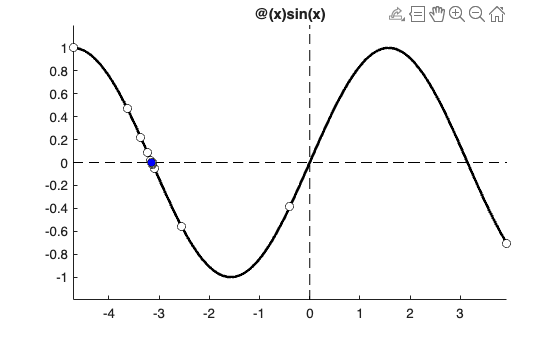


bisection_demo(@(x) sin(x),[-1.5*pi,1.25*pi]);

**Gradient-based methods**

- Requires function, f(x), and gradient, f'(x), evaluations

- Newton's method: $x_{k+1}=x_k-\frac{f(x_k)}{f'(x_k)}$

- Secant method: use finite differences to approximate gradients instead of analytic gradients (only requires function evaluations)

`EX. newton_demo.m`

Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Converged!


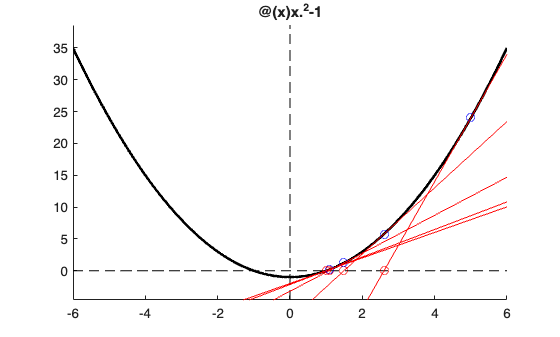

% Should work easily
newton_demo(@(x) x.^2-1,@(x) 2*x,5,[-6,6]);

Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Converged!


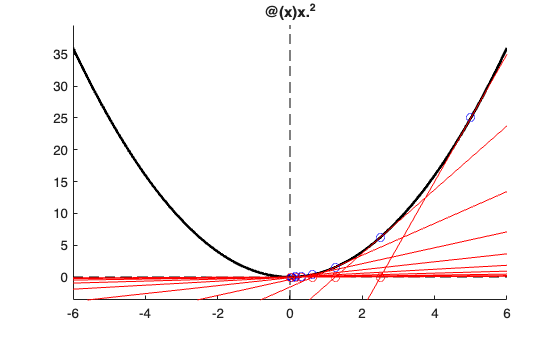


% Should work, but not easily (gradient -> 0 at solution)
newton_demo(@(x) x.^2,@(x) 2*x,5,[-6,6]);

Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Press any key to continue
Converged!


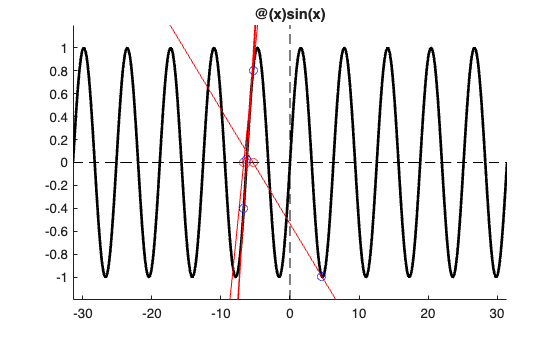


% Might work, but unpredictable, start near extrema
newton_demo(@(x) sin(x),@(x) cos(x),3*pi/2-0.1,[-10*pi,10*pi]);

`fzero` (for scalar functions)

- Derivative-free

- Combines bisection, secant, and interpolation methods

- `[x,fval,exitflag,output] = fzero(fun,x0,options)`

- a MATLAB builtin command for finding a root of a continuous, scalar-valued, univariate function

Ex.

[x1,fval1,exitflag1,output1] = fzero(@(x) x^2-1,4);

**Quiz. **

Try solving $x^2=0$ and $x^2+1=0$ using `fzero`. What do you get? How would you explain the results?

[x2,fval2,exitflag2,output2] = fzero(@(x) x^2,4);

Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -1.7162e+154 is Inf.)
Check function or try again with a different starting value.


[x3,fval3,exitflag3,output3] = fzero(@(x) x^2+1,4);

Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -1.7162e+154 is Inf.)
Check function or try again with a different starting value.


#### general case

**Derivative-free methods**

- Requires function, F(x), evaluations

- Fixed point iteration, Secant method, etc

**Gradient-based methods**

- Requires function and Jacobian evaluations

- Newton-Raphson method

- Gauss-Newton and Levenberg-Marquardt (nonlinear least squares: $\min \;\left|\right|F\left(x\right)\left|\right|$)

- Can use finite difference approximations to gradients instead of analytic gradients (only requires function evaluations)

`fsolve `(for vector-valued functions)

- Gradient-based

- `[x,fval,exitflag,output,jac] = fsolve(fun,x0,options)`

- Algorithms: standard trust region (default), trust region reflexive, Gauss-Newton, Levenberg-Marquardt

- By default uses finite differences to compute Jacobian; To supply analytic Jacobian, `fun` return Jacobian as second output and `options.Jacobian = 'on'`

Ex.

x0 = [1;1];
% without Jacobian information
[x1,f1,exit1,out1] = fsolve(@fsolve_func,x0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



% with Jacobian information
options = optimset('Jacobian','on');
[x2,f2,exit2,out2] = fsolve(@fsolve_func,x0,options);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



% number of function evaluations
out1.funcCount

ans = 25

out2.funcCount

ans = 9

### Types of Optimization Solvers

**Derivative-free**

Only function evaluations used

- Brute force

- Genetic algorithms

- Finite difference computations of gradients/Hessians

Usually require very large number of function evaluations

**Gradient-based**

Most popular class of techniques

Function and gradient evaluations used

- Finite difference computations of Hessians

- SPD updates to build Hessian approximations (BFGS)

**Hessian-based**

Hessians is usually difficult/expensive to compute, although often very sparse

Second-order optimality conditions

Function, gradient, and Hessian evaluations used

**Interior point methods**

Iterates always strictly feasible

Use barrier functions to keep iterates away from boundaries

Sequence of optimization problems

**Active set methods**

Active set refers to the inequality constraints active at the solution

Possibly infeasible iterates when constraints nonlinear

Minimize problem for given active set, then update active set based on Lagrange multipliers

**Globalization**: techniques to make optimization solver globally convergent (convergent to some local minima from any starting point)

- Trust region methods

- Line search methods

#### Linear Program (LP)


$${\textrm{minimize}}_{x\in R^{n_v } } \;f^T x$$



$$\begin{array}{l}
\textrm{subject}\;\textrm{to}\;\textrm{Ax}\le b\\
A_{\textrm{eq}} x{=b}_{\textrm{eq}} \\
l\le x\le u\;
\end{array}$$


**MATLAB solver (**`linprog`**)**

Medium-scale

- Simplex method

- `options = optimset('LargeScale', 'off', 'Simplex', 'on')`

Large-scale

- Primal-dual interior point method

- Default

**Demo**

Find the optimal combination of food that provides desired nutrients while minimizing the cost.

% Nutrients: [calories; protein; fiber; vitamin C]
% Food:      [subway tuna footlong, banana, egg, PB ]

cost = [6.5;1.0;0.25;0.10];
nutrients = [960,120,71,188;... % calories for each food
             40,1,6,8;... % protein for each food
             10,4,0,0;... % fiber for each food
             40,20,0,0]; % vitamin C for each food

f = cost;
A = [-nutrients;nutrients];
b = [ -[100;40;10;100] ; [2000;1000;1000;10000] ];
lower = [1;0;0;0];
upper = [inf;inf;inf;inf];

[x,fval,exitflag]=linprog(f,A,b,[],[],lower,upper)


Optimal solution found.



x =      1
     3
     0
     0


fval = 9.5000

exitflag = 1

**Binary integer linear program**

- x is a binary number, either 0 or 1

- NP-hard

- `bintprogram`

- `intlinprog: m`ixed-integer linear programming solver

#### Quadratic Program (QP)


$${\textrm{minimize}}_{x\in R^{n_v } } \;{\frac{1}{2}x^T \textrm{Hx}+f}^T x$$



$$\begin{array}{l}
\textrm{subject}\;\textrm{to}\;\;\;\;\textrm{Ax}\;\le \;b\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;A_{\textrm{eq}} x{\;=\;b}_{\textrm{eq}} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;l\le x\le u\;
\end{array}$$


**MATLAB solver (**`quadprog`**)**

Medium-scale

- Active-set method with linear subproblems

Large-scale

- Trust region reflexive method: Newton-type method, Preconditioned CG to solve linear system

#### Unconstrained Optimization


$${\textrm{minimize}}_{x\in R^{n_v } } \;f\left(x\right)$$


**MATLAB solvers**

`fminsearch`: Derivative-free, Simplex search

`fminunc`: Quasi-Newton with linesearch (medium scale), Trust region reflexive (large scale)

#### Linearly Constrained Optimization


$${\textrm{minimize}}_{x\in R^{n_v } } \;f\left(x\right)$$



$$\begin{array}{l}
\textrm{subject}\;\textrm{to}\;\textrm{Ax}\le b\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;{\;A}_{\textrm{eq}} x{=b}_{\textrm{eq}} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;l\le x\le u\;
\end{array}$$


Or only the box constraints.

**MATLAB solvers**

`fminbnd`: Single variable optimization

`fmincon`: Trust region reflexive method, Active-set method

#### Nonlinear Constraints

Solvers

- Trust region reflexive

- Sequential Quadratic Programming (SQP)

- Interior Point (IP)

#### Syntax for call to Optimization Toolbox

`[x,fval,exitflag,out,lam,grad,hess] = ...`

`solver(f,x0,A,b,Aeq,beq,lb,ub,nlcon,opt)`

`[x,fval,exitflag,out,lam,grad,hess] = solver(problem)`

**Inputs**

- `f - `function handle (or vector for LP) defining objective function (and gradient)

- `x0 - `vector defining initial guess

- `A,b - `matrix, RHS defining linear inequality constraints

- `Aeq, beq - `matrix, RHS defining linear equality constraints

- `lb,ub -` vectors defining lower, upper bounds

- `nlcon -` function handle defining nonlinear contraints (and Jacobians)

- `opt -` optimization options structure

- `problem -` structure containing above information

**Outputs**

- `x - `minimum found

- `fval - `value of objective function at x

- `exitflag - `describes exit condition of solver

- `out - `structure containing output information

- `lam - `structure containing Lagrange multipliers at x

- `grad - `gradient of objective function at x

- `hess - `Hessian of objective function at x

Instead of specifying many different inputs in a call to the optimizer, store inputs in `problem`** structure** with fields `objective, x0, Aineq, bineq, Aeq, beq, lb, ub, nonlcon, solver, options.`

Each optimization solver has tunable options that can be specified with an `options`** structure.**

- `optimset <solver> `to return options available for particular solver, along with default values

#### Demo

Consider the following *nonlinearly constrained* optimization problem:

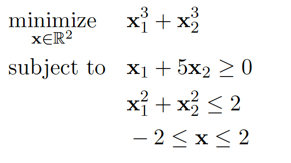

- Derive derivative information for objective and nonlinear constraints.

- Convert optimization problem into MATLAB compatible form.

- Solve using `fmincon.`

addpath([pwd,'/demo'])
x0 = [1;1];
A  = [-1,-5];
b  = 0;
lb = [-2;-2];
ub = [2;2];

% turn on: 
%   user-defined gradients for the nonlinear constraints
%   user-defined gradients for the objective functions
%   display of output at each iteration
options = optimset('GradConstr','on', 'GradObj','on', 'Display', 'iter');
[xstar,fstar exitflag output] = fmincon(@fmincon_obj,x0,A,b,[],[],lb,ub,@fmincon_constr, options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.000000e+00    0.000e+00    2.999e+00
    1       2    1.534614e+00    0.000e+00    2.426e+00    1.345e-01
    2       4    5.719201e-01    0.000e+00    2.037e+00    1.115e+00
    3       5    2.039270e-02    0.000e+00    2.430e-01    6.545e-01
    4       6    1.935173e-02    0.000e+00    8.523e-02    1.144e-01
    5       7    1.417678e-02    0.000e+00    6.583e-02    2.936e-02
    6       9    6.918852e-03    0.000e+00    1.971e-02    6.735e-02
    7      10    2.487049e-03    0.000e+00    1.950e-02    6.267e-02
    8      11    7.779248e-04    0.000e+00    7.113e-03    4.829e-02
    9      12    2.575702e-04    0.000e+00    6.121e-03    3.109e-02
   10      13    1.082255e-04    0.000e+00    1.099e-03    1.737e-02
   11      14    7.231173e-05    0.000e+00    4.375e-04    6.412e-03
   12      15    6.703952e-05    0.000e+00    2

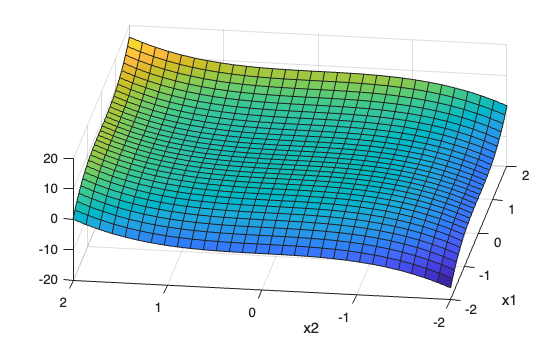

[X,Y] = meshgrid(linspace(lb(1),ub(1),30),linspace(lb(2),ub(2),30));
F = zeros(size(X));
C = zeros(size(X));
AA = zeros(size(X));

for i = 1:size(X,1)
    for j = 1:size(X,2)
        F(i,j) = fmincon_obj([X(i,j),Y(i,j)]);
        C(i,j) = fmincon_constr([X(i,j),Y(i,j)]);
        AA(i,j)= A*[X(i,j);Y(i,j)];
    end
end

% plot the objective function
figure;
h(1) = surf(X,Y,F);
xlabel('x1'); ylabel('x2');
view(gca,[-81.5 48]);

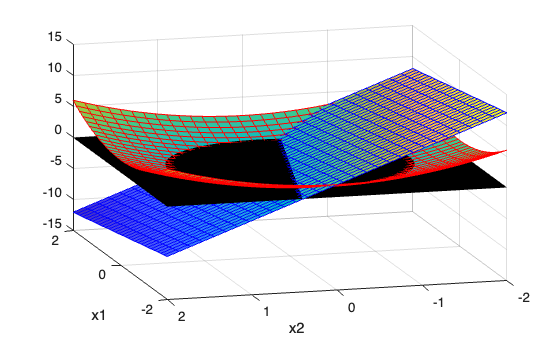

% plot the constraints
figure;
h(2) = surf(X,Y,C,'edgecolor','r'); hold on;
h(3) = surf(X,Y,AA,'edgecolor','b');
h(4) = surf(X,Y,0*F,'edgecolor','none','facecolor','k');
xlabel('x1'); ylabel('x2');
view(gca,[-105.5 21.0]);

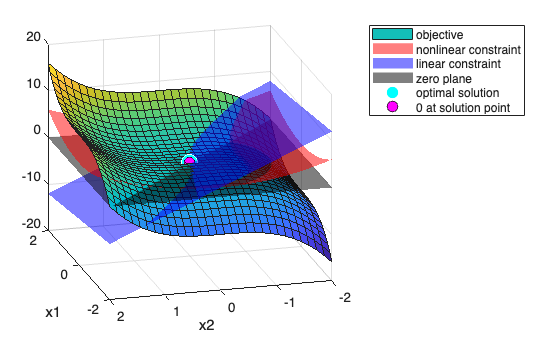

figure;
h(5) = surf(X,Y,F); hold on;
h(6) = surf(X,Y,C,'edgecolor','none','facecolor','r','facealpha',0.5);
h(7) = surf(X,Y,AA,'edgecolor','none','facecolor','b','facealpha',0.5);
h(8) = surf(X,Y,0*F,'edgecolor','none','facecolor','k','facealpha',0.5);
h(9) = plot3(xstar(1),xstar(2),fstar,'co','markersize',12,...
    'markerfacecolor','c','markeredgecolor','w');
h(10) = plot3(xstar(1),xstar(2),0,'mo','markersize',8,...
    'markerfacecolor','m','markeredgecolor','k');
xlabel('x1'); ylabel('x2');
view(gca,[-105.5 21.0]);
legend("objective","nonlinear constraint","linear constraint",...
"zero plane","optimal solution","0 at solution point")

### Optimize Live Editor Task

Interactively create and solve optimization problems with MATLAB, Optimization Toolbox, or Global Optimization Toolbox using a visual interface. See [https://www.mathworks.com/videos/how-to-use-the-optimize-live-editor-task-1594660384855.html](https://www.mathworks.com/videos/how-to-use-the-optimize-live-editor-task-1594660384855.html) for an introduction video.

- Insert -> Task -> Optimize to launch

- User-friendly

- Problem-based or Solver-based from workspace

% Create problem
problem = optimproblem;

% Display problem information
show(problem);


  OptimizationProblem : 

  No problem defined.


disp('Please select: Objective function, Initial point (x0)')

**Parallel Computations** available with commands `fmincon, fminattain, fminimax`

Start MATLAB pool of workers

Set `UseParallel` option to 'always'

`parfor` to loop over multiple initial conditions

- Attempt at global optimization

- Embarrassingly parallel

# Fintech Demo: Simple Constrained Portfolio Optimization + Walk-Forward Backtest

Our code roughly does the following

- Download daily ETF prices (CSV) from Stooq

- Align dates, compute daily simple returns

- Monthly walk-forward mean-variance optimization via quadprog 

- Apply transaction costs at rebalances

- Compare vs equal-weight and buy&hold SPY

clear; clc; close all;

tickers = {'SPY','QQQ','IWM','EFA','EEM','AGG','TLT','GLD','VNQ'}; % These are 9 liquid ETFs
n = numel(tickers);

lookback = 252; % rolling estimation window
gamma = 5; % return/risk tradeoff parameter (boost this for more agressive strategy)
ridge = 1e-6; % covariance ridge for numerical stability. On one hand, it may feel like bookkeeping, but it costs us nothing to add. Even in this example, it improves our sharpe ratio in some cases and this would translate to actual performance improvements in the real world.  

wMax = 0.5; % max weight per ETF
tc = 0.0005; % transaction cost coefficient (per unit turnover)
yearsToKeep = 7; % keep last N years after alignment (>= 5 years required)

% Download daily ETF prices from Stooq
priceTTs = cell(n,1);
wOpts = weboptions('Timeout', 30);
for i = 1:n
    sym = lower(tickers{i});
    url = sprintf('https://stooq.com/q/d/l/?s=%s.us&i=d', sym);
    csvFile = fullfile(tempdir, sprintf('%s.us.csv', sym));

    % Download the stock prices
    try
        websave(csvFile, url, wOpts);
    catch ME
        error('Failed to download %s from Stooq.\nURL: %s\nError: %s', tickers{i}, url, ME.message);
    end

    opts = detectImportOptions(csvFile);
    T = readtable(csvFile, opts);

    vnames = T.Properties.VariableNames;
    hasDate = any(strcmpi(vnames, 'Date'));
    hasClose = any(strcmpi(vnames, 'Close'));

    dateCol = T{:, find(strcmpi(vnames, 'Date'), 1)};
    dt = dateCol;
    
    closeCol = T{:, find(strcmpi(vnames, 'Close'), 1)};
    closePx = closeCol;

    % Clean + sort (pretty sure this step is not really necessary actually.
    % This data is pretty clean as is...
    good = isfinite(closePx) & ~isnat(dt);
    dt = dt(good);
    closePx = closePx(good);
    [dt, idx] = sort(dt);
    closePx = closePx(idx);

    priceTTs{i} = timetable(dt, closePx, 'VariableNames', tickers(i));
end

% Align dates
pricesTT = priceTTs{1};
for i = 2:n
    pricesTT = synchronize(pricesTT, priceTTs{i}, 'intersection');
end
pricesTT = rmmissing(pricesTT);

% Keep last N years
endDate = pricesTT.Properties.RowTimes(end);
startDate = endDate - calyears(yearsToKeep);
if pricesTT.Properties.RowTimes(1) < startDate
    pricesTT = pricesTT(pricesTT.Properties.RowTimes >= startDate, :);
end

%% Compute daily returns (difference between price at closing times for each day)
P = pricesTT{:,:};
datesP = pricesTT.Properties.RowTimes;
R = P(2:end,:)./P(1:end-1,:) - 1;
datesR = datesP(2:end);
Tret = size(R,1);

% Monthly rebalance schedule (first trading day of each month) + 252-day burn-in
ym = year(datesR)*100 + month(datesR);
[~, firstOfMonthIdx] = unique(ym, 'stable');

rebIdxAll = firstOfMonthIdx;
rebIdx = rebIdxAll(rebIdxAll > lookback); % burn-in: need 252 prior returns

if isempty(rebIdx)
    error('Not enough data for a %d-day lookback window.', lookback);
end

btStart = rebIdx(1); % first rebalance after burn-in
rebSet = false(Tret,1);
rebSet(rebIdx) = true;

%% Walk-forward backtest (Optimized QP vs Equal-Weight vs Buy&Hold SPY)
rOpt = nan(Tret,1);
rEq  = nan(Tret,1);
rSpy = nan(Tret,1);
turnoverOpt = zeros(Tret,1);
turnoverEq  = zeros(Tret,1);
% Start from "cash", meaning all-zero weights. First rebalance includes entry cost.
wOpt = zeros(n,1);
wEq  = zeros(n,1);
spyIdx = find(strcmp(tickers, 'SPY'), 1);

% quadprog setup: min 0.5*w'*H*w + f'*w
Aeq = ones(1,n);
beq = 1;
lb  = zeros(n,1);
ub  = wMax*ones(n,1);
qpOptions = optimoptions('quadprog', ...
    'Algorithm', 'interior-point-convex', ...
    'Display', 'off');

for t = btStart:Tret
    costOpt = 0;
    costEq  = 0;
    costSpy = 0;

    if rebSet(t)
        % Rolling mean/cov estimates from the previous 252 daily returns
        window = R(t-lookback:t-1, :);
        mu = mean(window, 1)';
        Sigma = cov(window);
        Sigma = (Sigma + Sigma')/2; % Goofy symmetrize stability stuff
        Sigma = Sigma + ridge*eye(n); % Goofy ridge for PSD-ness

        % Solve QP: min 0.5*w'*Sigma*w - gamma*mu'*w
        H = (Sigma + Sigma')/2;
        f = -gamma*mu;

        [wNew, ~, exitflag] = quadprog(H, f, [], [], Aeq, beq, lb, ub, [], qpOptions);

        % Fallback if the solver fails. Certainly important to have in a
        % production environment!
        isBad = (exitflag <= 0) || any(~isfinite(wNew)) || (abs(sum(wNew) - 1) > 1e-6);
        if isBad
            if abs(sum(wOpt) - 1) < 1e-6
                wNew = wOpt;
            else
                wNew = ones(n,1)/n;
            end
        end

        dW = wNew - wOpt;
        turnoverOpt(t) = sum(abs(dW));
        costOpt = tc * turnoverOpt(t);
        wOpt = wNew;

        % Equal-weight baseline
        wNewEq = ones(n,1)/n;
        dW_eq = wNewEq - wEq;
        turnoverEq(t) = sum(abs(dW_eq));
        costEq = tc * turnoverEq(t);
        wEq = wNewEq;

        % Buy-and-hold SPY: we buy it and hodl. Therefore, only the entry
        % fee once at the start.
        if t == btStart
            costSpy = tc * 1.0;
        end
    end

    % Daily realized returns
    rOpt(t) = wOpt' * R(t,:)' - costOpt;
    rEq(t) = wEq' * R(t,:)' - costEq;
    rSpy(t) = R(t, spyIdx) - costSpy;
end

% Plotting the results
datesBT = datesR(btStart:end);
rOptBT = rOpt(btStart:end);
rEqBT = rEq(btStart:end);
rSpyBT = rSpy(btStart:end);

startPlotDate = datesR(btStart-1);
eqDates = [startPlotDate; datesBT];

eqOpt = [1; cumprod(1 + rOptBT)];
eqEq = [1; cumprod(1 + rEqBT)];
eqSpy = [1; cumprod(1 + rSpyBT)];

sOpt = perfStats(rOptBT);
sEq = perfStats(rEqBT);
sSpy = perfStats(rSpyBT);

Summary = table( ...
    {'Optimized QP'; 'Equal-Weight'; 'Buy&Hold SPY'}, ...
    100*[sOpt.annRet; sEq.annRet; sSpy.annRet], ...
    100*[sOpt.annVol; sEq.annVol; sSpy.annVol], ...
        [sOpt.sharpe; sEq.sharpe; sSpy.sharpe], ...
    100*[sOpt.maxDD;  sEq.maxDD;  sSpy.maxDD], ...
    'VariableNames', {'Strategy','AnnReturnPct','AnnVolPct','Sharpe0','MaxDrawdownPct'} );

        Strategy        AnnReturnPct    AnnVolPct    Sharpe0    MaxDrawdownPct
    ________________    ____________    _________    _______    ______________

    {'Optimized QP'}       18.566        16.639       1.1073        29.156    
    {'Equal-Weight'}       9.8519        14.605      0.71675        25.957    
    {'Buy&Hold SPY'}       16.574        20.641      0.84659         28.32    




disp(Summary);
% Turnover diagnostics
avgTurnOpt = mean(turnoverOpt(rebIdx));


Average turnover per rebalance:


avgTurnEq  = mean(turnoverEq(rebIdx));

Optimized QP:  43.22%


fprintf('\nAverage turnover per rebalance:\n');

Equal-Weight:   1.39%


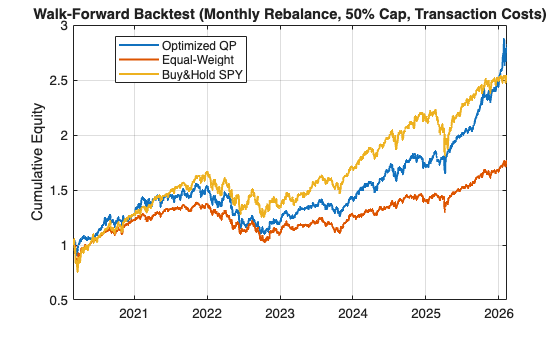

fprintf('Optimized QP: %6.2f%%\n', 100*avgTurnOpt);
fprintf('Equal-Weight: %6.2f%%\n', 100*avgTurnEq);
figure('Color','w');
plot(eqDates, eqOpt, 'LineWidth', 1.5); hold on;
plot(eqDates, eqEq,  'LineWidth', 1.5);
plot(eqDates, eqSpy, 'LineWidth', 1.5);
grid on; box on;
ylabel('Cumulative Equity');
title('Walk-Forward Backtest (Monthly Rebalance, 50% Cap, Transaction Costs)');

legend('Optimized QP','Equal-Weight','Buy&Hold SPY','Location','best');
xlim([eqDates(1) eqDates(end)]);
% Helper function which takes in daily returns and computes various
% performance statistics for us
function s = perfStats(r)
    r = r(:);
    annFactor = 252;

    % Annualized return: average yearly growth rate of the strategy.
    equity = [1; cumprod(1 + r)];
    years = numel(r) / annFactor;
    s.annRet = equity(end)^(1/years) - 1;

    % Annualized volatility: how much returns fluctuate over a typical year.
    s.annVol = std(r, 0) * sqrt(annFactor);

    % Sharpe ratio (rf = 0): return earned per unit of risk (higher is better).
    muDaily = mean(r);
    sigDaily = std(r, 0);
    s.sharpe = (muDaily / sigDaily) * sqrt(annFactor);

    % Maximum drawdown: worst percentage loss from a previous peak.
    runningMax = cummax(equity);
    dd = equity ./ runningMax - 1;
    s.maxDD = -min(dd);
end